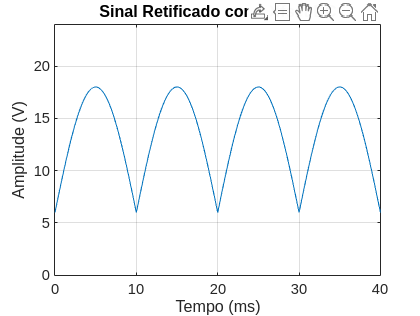

%% Seção 1 - Geração do Sinal (Executar Primeiro)
f = 50;           % Frequência da senoide (5 kHz)
A = 12;             % Amplitude (V)
offset = 6;         % Componente DC (V)
Fs = 10000;       % Frequência de amostragem (500 kHz)
duration = 0.04;   % Duração do sinal (1 ms)

t = 0:1/Fs:duration; 
y = A * sin(2*pi*f*t); 
y_ret = abs(y) + offset; 

% Salvar dados para as próximas seções
save('dados_sinal.mat', 't', 'y_ret', 'Fs'); 

figure;
plot(t*1000, y_ret);
xlabel('Tempo (ms)');
ylabel('Amplitude (V)');
title('Sinal Retificado com Offset DC');
ylim([0 24]);       % Amplitude entre 6 e 18
grid on;
saveas(gcf, 'Sinal_Retificado.png');